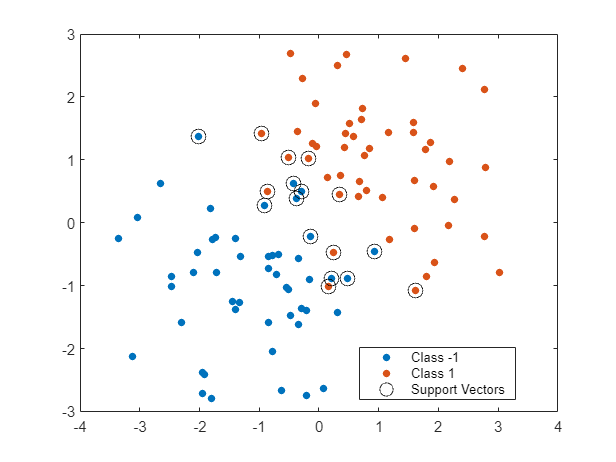

rng(1) %for reproduciability and to use the same randn function later
        %but with different values for testing
        
X = [randn(50,2)+1; randn(50,2)-1];
Y = [ones(50,1); -ones(50,1)];
Mdl1 = fitcsvm(X,Y);

figure('Name','SVM Model 1');
gscatter(X(:,1),X(:,2), Y);
hold on
plot(Mdl1.SupportVectors(:,1), Mdl1.SupportVectors(:,2), 'ko', 'MarkerSize',10)
hold off
legend('Class -1', 'Class 1', 'Support Vectors')

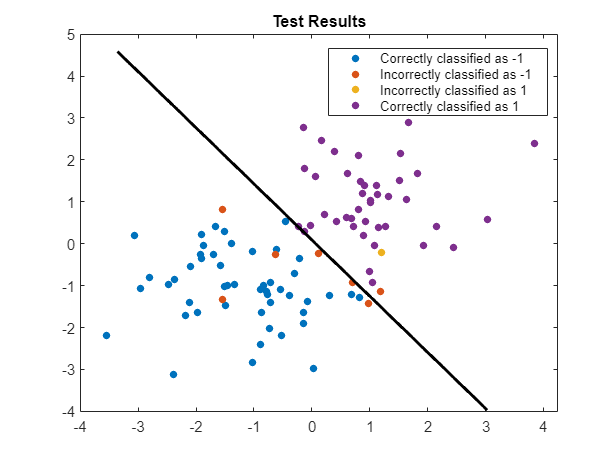

% testing with a new set of randomly generated data
rng(2);

Xtest = [randn(50,2)+1; randn(50,2)-1];
Ytest = [ones(50,1); -ones(50,1)];
YtestPred = predict(Mdl1,Xtest);

% Compute the slope and intercept of the decision boundary
w = Mdl1.Beta(1,:);
b = Mdl1.Bias;
m = -w;
c = -b/w;

gscatter(Xtest(:,1),Xtest(:,2), {YtestPred, Ytest});
hold on
% Plot the decision boundary
x1 = linspace(min(X(:,1)), max(X(:,1)), 100);
x2 = m*x1 +c;
plot(x1, x2, '-k', 'LineWidth', 2);
hold off
legend('Correctly classified as -1', 'Incorrectly classified as -1', ...
        'Incorrectly classified as 1', 'Correctly classified as 1')
title('Test Results')

Note: why is observation 8 (incorrectly) classified as -1 when it is on the class 1 side of the decision boundary? Did I draw it incorrectly?